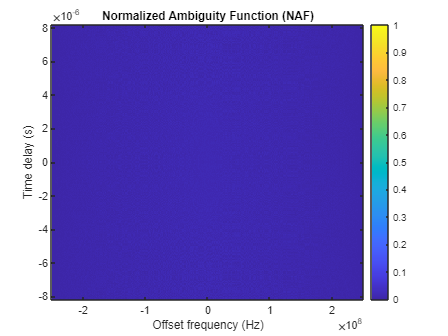

% Define M-sequence parameters
mSeqOrder = 12; % Order of the M-sequence
fs = 500e6; % Sample rate of the PRBS
mSeqLength = 2^mSeqOrder - 1; % Length of the M-sequence

% Generate M-sequence using Communications System Toolbox
hSeqGen = comm.PNSequence('Polynomial', [12 6 4 1 0], ...
                          'SamplesPerFrame', mSeqLength, ...
                          'InitialConditions', [1 zeros(1, mSeqOrder-1)]);
mSeq = step(hSeqGen);
mSeq = double(mSeq); % Convert logical to double for processing

% Convert M-sequence to bipolar (-1 and 1)
mSeqBipolar = 2 * mSeq - 1;

% Define the range of Doppler shifts and time delays for the ambiguity function
dopplerShifts = linspace(-fs/2, fs/2, mSeqLength);
ambFunc = zeros(length(dopplerShifts), 2*mSeqLength-1);

% Calculate the ambiguity function
for i = 1:length(dopplerShifts)
    % Apply Doppler shift by multiplying with a complex exponential
    dopplerShiftedSeq = mSeqBipolar .* exp(1j * 2 * pi * dopplerShifts(i) * (0:mSeqLength-1)' / fs);
    % Calculate cross-correlation with Doppler-shifted sequence
    ambFunc(i, :) = xcorr(dopplerShiftedSeq, mSeqBipolar);
end
  
% Normalize ambiguity function
ambFunc = abs(ambFunc);
ambFunc = ambFunc / max(ambFunc(:));

% Plot the ambiguity function
tGrid = (-mSeqLength+1):(mSeqLength-1);
tGrid = tGrid / fs; % Convert sample lags to time
figure;
imagesc(dopplerShifts, tGrid, ambFunc);
xlabel('Offset frequency (Hz)');
ylabel('Time delay (s)');
title('Normalized Ambiguity Function (NAF)');
colorbar;
axis xy;

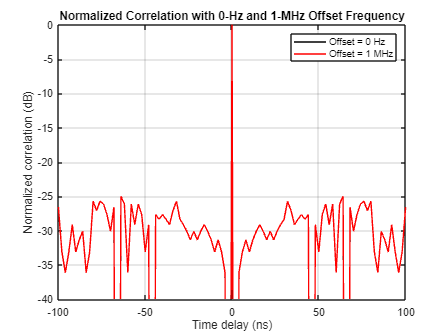



% Assuming mSeqBipolar and fs have been defined earlier in your code

% Time vector for the sequence
N = length(mSeqBipolar);
timeVector = (0:N-1)'/fs;

% Define the frequency offsets for the correlation calculations
offsets = [0, 1e6];  % 0 Hz and 1 MHz

% Initialize vectors to store normalized correlations
normCorr0Hz = zeros(2*N-1, 1);
normCorr1MHz = zeros(2*N-1, 1);

% Calculate auto-correlation for the non-shifted sequence (0 Hz offset)
autoCorr = xcorr(mSeqBipolar);
normCorr0Hz = autoCorr / max(abs(autoCorr));

% Now for the 1 MHz offset, apply the frequency shift
freqOffset = offsets(2); % 1 MHz offset
mSeqShifted = mSeqBipolar .* exp(-1j*2*pi*freqOffset*timeVector);
autoCorrShifted = xcorr(mSeqShifted);
normCorr1MHz = autoCorrShifted / max(abs(autoCorrShifted));

% Prepare the time axis in nanoseconds for plotting
lags = (-N+1):(N-1);
timeLags = lags / fs * 1e9; % Convert to nanoseconds for the plot

% Plotting
figure;
plot(timeLags, 10*log10(abs(normCorr0Hz)), 'k'); % Zero offset in dB
hold on;
plot(timeLags, 10*log10(abs(normCorr1MHz)), 'r'); % 1 MHz offset in dB
xlabel('Time delay (ns)');
ylabel('Normalized correlation (dB)');
title('Normalized Correlation with 0-Hz and 1-MHz Offset Frequency');
legend('Offset = 0 Hz', 'Offset = 1 MHz');
xlim([-100, 100]); % Match the x-axis scale to the provided graph
ylim([-40, 0]); % Adjust the y-axis limits to match the scale in dB
grid on;
hold off;

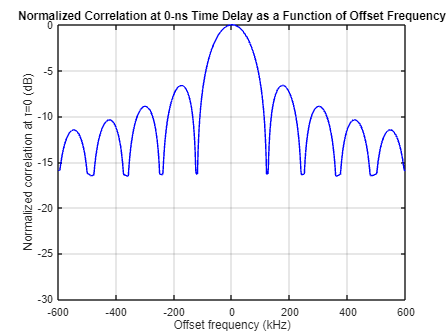




% Define frequency offsets in kHz
freqOffsets_kHz = linspace(-600, 600, 800) * 1e3; % From -400 kHz to 400 kHz


% Initialize the vector for the correlation at zero time delay
correlationAtZeroDelay = zeros(size(freqOffsets_kHz));

% Calculate the correlation for each frequency offset
for i = 1:length(freqOffsets_kHz)
    % Apply the frequency shift
    freqShift = freqOffsets_kHz(i);
    mSeqShifted = mSeqBipolar .* exp(-1j*2*pi*freqShift*timeVector);
    % Calculate the auto-correlation
    autoCorr = xcorr(mSeqBipolar, mSeqShifted);
    % Find the peak of the auto-correlation (at zero time delay)
    correlationAtZeroDelay(i) = max(abs(autoCorr));
end

% Normalize the correlation at zero time delay
normCorrelationAtZeroDelay = 10 * log10(correlationAtZeroDelay / max(correlationAtZeroDelay));

% Plotting
figure;
plot(freqOffsets_kHz/1e3, normCorrelationAtZeroDelay, 'b');
xlabel('Offset frequency (kHz)');
ylabel('Normalized correlation at τ=0 (dB)');
title('Normalized Correlation at 0-ns Time Delay as a Function of Offset Frequency');
xlim([-600, 600]); % Match the x-axis scale to the provided graph
ylim([-30, 0]); % Adjust the y-axis limits to match the scale in dB
grid on;